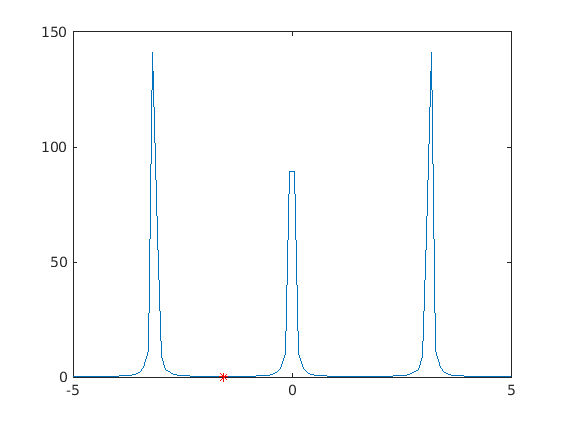

% 1.b
a = 0;
b = 2*pi/3;
x = linspace(-5, 5, 100);
F = 1./((a*cos(x)+b*sin(x)).^2);
f = @(x) 1./(a*cos(x)+b*sin(x)).^2;
plot(x, F);
v = ginput(2);
[min_x, min_y] = fminbnd(f,v(1,1),v(2,1));
hold on;
plot(min_x, min_y,'r*');
hold off;

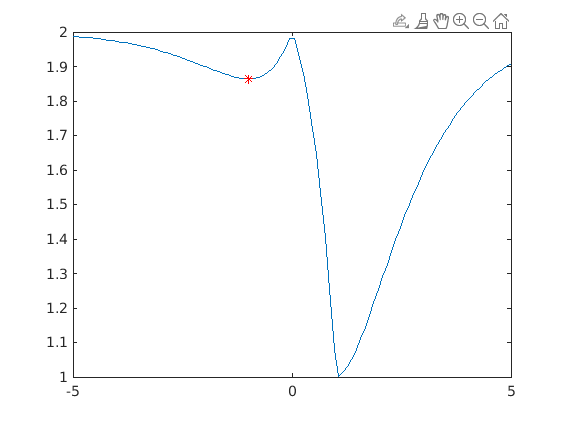

% 1.c
a = 0; b = 4;
x = linspace(-5, 5, 100);
F = 2 - abs(x).*exp(-abs(x-1));
f = @(x) 2 - abs(x).*exp(-abs(x-1));
plot(x, F);
v = ginput(2);
[min_x, min_y] = fminbnd(f,v(1,1),v(2,1));
hold on;
plot(min_x, min_y,'r*');
hold off;

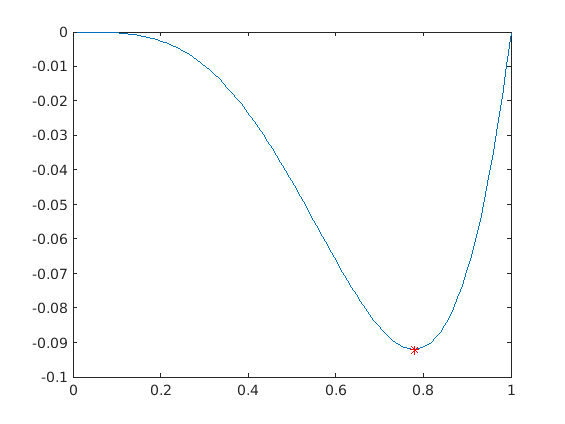

% 2.a
a = 4;
x = linspace(0, 1, 100);
F = x.^a.*log(x);
f = @(x) x.^a.*log(x);
plot(x, F);
[min_x, min_y] = fminbnd(f,x(1),x(100));
hold on;
plot(min_x, min_y,'r*');
hold off;